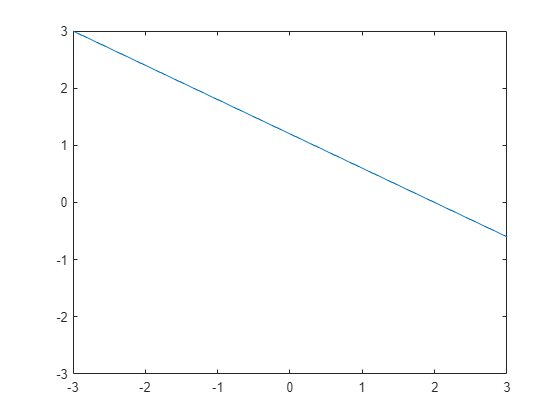

clear;
t=-3:0.1:3;
x0 = 2; y0 = 0; Ax = 5; Ay = -3;
X = @(t) x0 + Ax*t;
Y = @(t) y0 + Ay*t;

rectDot1 = [-3, 3];
rectDot2 = [3, -3];

N = 10;
r = 0.7;

x = X(t);
y = Y(t);
p = plot(x,y);
axis([rectDot1(1) rectDot2(1) rectDot2(2) rectDot1(2)]);

clear;
g = 9.81;
L = 1;
syms y(t)
Dy = diff(y);

ode = diff(y,t,2) ==-g/L*sin(y);
cond1 = y(0) == 0;
cond2 = Dy(0) == 1;
conds = [cond1 cond2];
ySol(t) = dsolve(ode,conds);

ySol = simplify(ySol)

 
ySol(t) =
 
[ empty sym ]
 


clear;
% Define parameters
g = 9.81; % Acceleration due to gravity (m/s^2)
L = 1; % Suspension length (m)

% Define initial conditions
theta0 = pi/6; % Initial angle (radians)
omega0 = 2; % Initial angular velocity (radians/s)

% Define time range and step size
t0 = 0; % Initial time (s)
tf = 30; % Final time (s)
h = 0.01; % Time step size (s)

% Define function for differential equation
f = @(t, y) [y(2); -g/L*sin(y(1))];

% Use fourth-order Runge-Kutta method to solve differential equation
[t, y] = ode45(f, t0:h:tf, [theta0, omega0]);

% % Plot angle vs. time
% figure();
% plot(t, y(:, 1));
% xlabel('Time (s)');
% ylabel('Angle (rad)');
% title('Mathematical Pendulum');
% hold off;
% Define animation parameters
fps = 30; % Frames per second
speedup = 10; % Speedup factor
dt = 1/(fps*speedup); % Time step for animation
scale = 1; % Scale factor for visualization

% Create figure window
fig = figure();
figure(fig);
ampl = subplot(3,1,1);
anim = subplot(3,1,[2 3]);


% Initialize pendulum position
x0 = 0;
y0 = 0;

hold(anim,"on");
line = plot(anim,[x0, x0], [y0, y0], 'b-', 'LineWidth', 2);
dot = plot(anim,x0, y0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
set(anim, 'xlim', [-1 1], 'ylim', [-1 0]);

hold(ampl,"on");
amplitude = plot(ampl,t, y(:,1), 'k-', 'LineWidth', 2);
massdot = plot(ampl,t(1), y(1,1), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Loop over time steps
for i = 1:length(t)
    % Calculate position of pendulum
    x1 = x0 + L*sin(y(i, 1))*scale;
    y1 = y0 - L*cos(y(i, 1))*scale;
    
    % Plot pendulum
    set(line, 'xData',[x0, x1], 'yData', [y0, y1]);
    set(dot,'xData', x1, 'yData',y1);
    set(massdot, 'XData', t(i), 'YData', y(i,1));
    % Update pendulum position
    %x0 = x1;
    %y0 = y1;
    
    % Pause to create animation effect
    pause(dt);
end
hold(anim,"off");
hold(ampl, "off");

clear;
